### **Group: Aleix Granero, Michal Szabó**

**10.11.2021**

clc; clear

# Practice 4. Gradient Images and Singular points

## The Harris & Stephens corner detection algorithm

### Exercise: Create a MATLAB code that calculates the ${\mathit{\mathbf{M}}}_{\mathit{\mathbf{C}}}$value for all the pixels in a gray input image $\mathit{\mathbf{I}}\left(\mathit{\mathbf{x}},\mathit{\mathbf{y}}\right)$. 

I = imread("images\chess.jpg");
I = rgb2gray(I);

**Step.1:** Calculate the matrices $I_x$and $I_y$, the partial derivatives of $I\left(x,y\right)$

sobelx = [-1 0 1;-2 0 2;-1 0 1];
sobely = [-1 -2 -1;0 0 0;1 2 1];
laplacex = [0 1 0;1 -4 1;0 1 0];
laplacey = [1 1 1;1 -8 1;1 1 1];

Ix = imfilter(I,sobelx);
Iy = imfilter(I,sobely);

**Step.2:** Calculate the matrices ${I^2 }_x$and $I_y^2$, the partial derivatives of $I_x \;\ldotp I_y$

Ix2 = Ix.^2;
Iy2 = Iy.^2;
Ixy = Ix.*Iy;

**Step.3: **Show these matrices as gray level images and combined in a RGB image (pseudocolor)

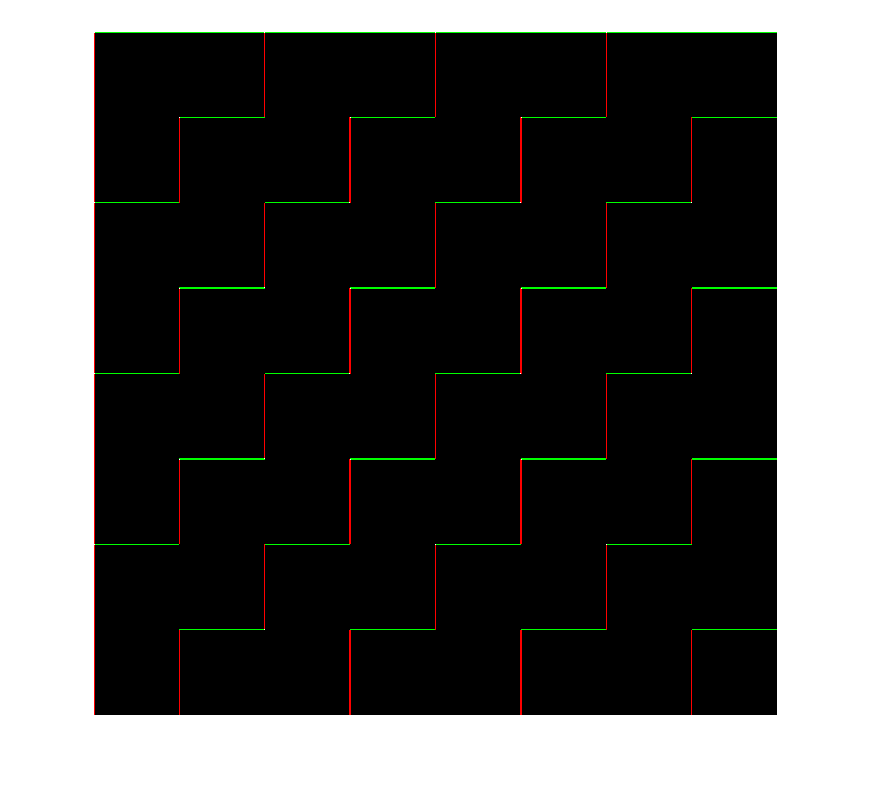

Image = cat(3,Ix2,Iy2,Ixy);
figure, imshow(Image)

**Step.4: **Average the results with a Gaussian filter and build the A matrix for every pixel of the original image.


$$A=\left\lbrack \begin{array}{cc}
{I^2 }_x  & I_x \;\ldotp I_y \\
I_x \;\ldotp I_y  & {I^2 }_y 
\end{array}\right\rbrack$$


sigma = 3;
mask = fspecial('gaussian',sigma);

Ix2g = imfilter(Ix2,mask);
Ixyg = imfilter(Ixy,mask);
Iy2g = imfilter(Iy2,mask);

**Step.5: **For every pixel calculate the function , from det(A) and trace(A). 

Trace = Ix2g+Iy2g;
Det = Ix2g.*Iy2g-Ixyg.^2;

**Step.6 : **Test for different values of k.

k = 0.15;
Mc = Det-k.*Trace.^2;

**Step.7 : **Present the results as an output gray image Mc.

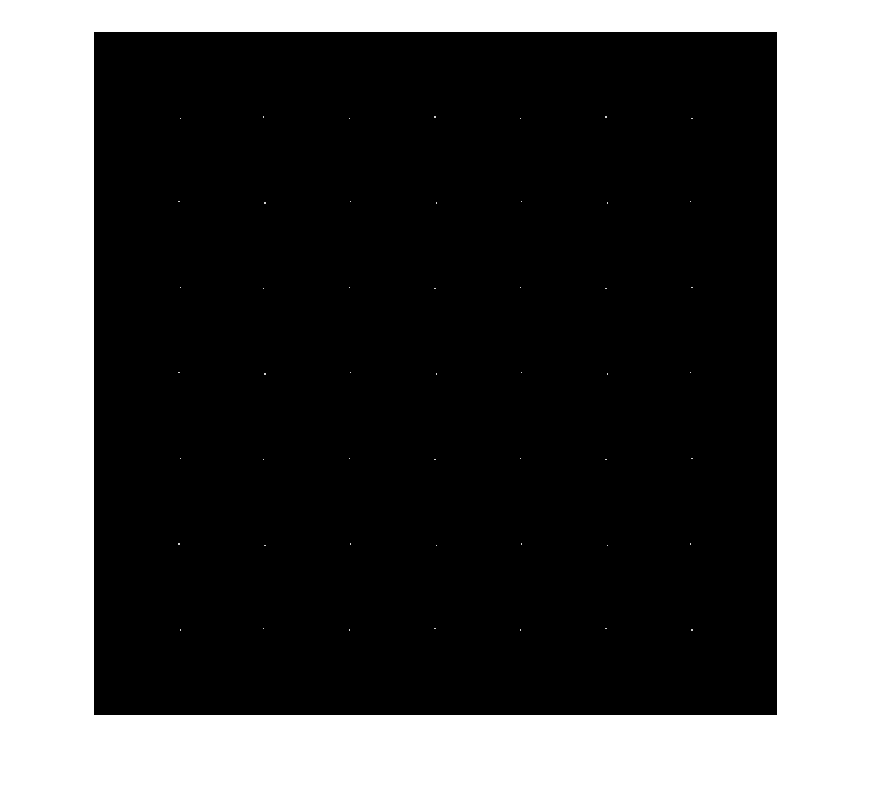

figure
imshow(Mc)

### **Displaying corners on the image**

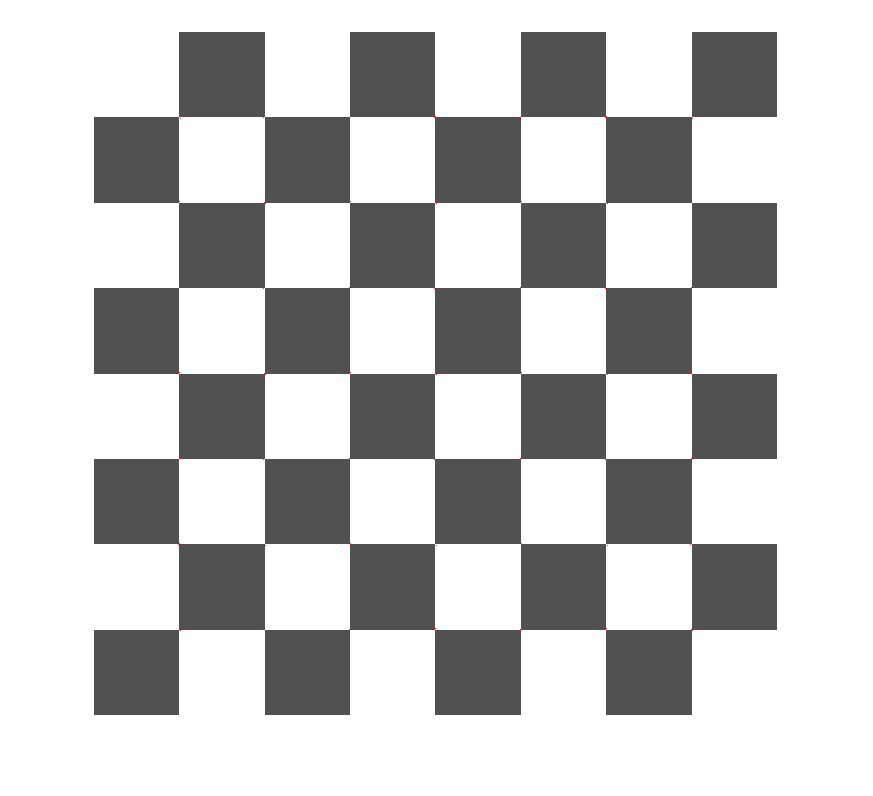

% My located points
eqMc = uint8(Mc);
I_corners = cat(3, I+eqMc, I-eqMc, I-eqMc);
% These points can be seen only by zooming into the image
figure, imshow(I_corners)

### **Finding locations of the sigular points and comparing them with MATLAB functions**

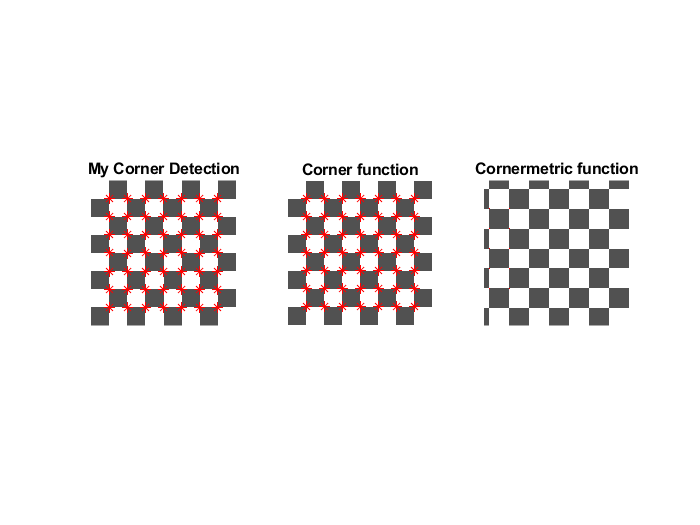

% Because the corner in our image is defined by four points we are gonna
% apply the following masks to find the exact position of the corner
% displayed by only one point
mask1 = [-1 0 1];
Mc1 = imfilter(Mc,mask1);
mask2 = [-1;0;1];
Mc2 = imfilter(Mc1,mask2);
mask3 = [-1 0 1];
Mc3 = imfilter(Mc2,mask3);
mask4 = [-1;0;1];
Mc4 = imfilter(Mc3,mask4);

c = max(max(Mc4))*0.9; % Points with 90% of max value in Mc
[y,x] = find(Mc4>c);  % finding these points in Mc matrix

% Since we move the points by applying the masks we move them back
x = x(:)+3; 
y = y(:)+3;

% Displaying detected corners
figure, 
subplot(1,3,1), imshow(I), hold on,
subplot(1,3,1), plot(x(:),y(:),'r*'), hold off,  %used with few singular points
% subplot(1,3,1), plot(x(:),y(:),'r.','MarkerSize',0.01), hold off,
title("My Corner Detection")


% Located points using corner() function
subplot(1,3,2), C = corner(I); imshow(I), hold on, 
subplot(1,3,2), plot(C(:,1),C(:,2),'r*'), hold off;
title("Corner function")


% located points using cornermetric() function 
filter = [0.25 0.5 0.25];
C2 = cornermetric(I,'FilterCoefficients',filter);
corner_peaks = imregionalmax(C2);
corner_idx = find(corner_peaks == true);
[r,g,b] = deal(I);
r(corner_idx) = 255;
g(corner_idx) = 0;
b(corner_idx) = 0;
RGB = cat(3,r,g,b);
subplot(1,3,3), imshow(RGB),
title("Cornermetric function")

# Report

#### Developed work

We are using the Harris & Stephens corner detection algorithm to find corners in the images. 

First of all we divide the image into two images $I_x$ and $I_y$ using sobel filter with. From these two images we create another three images $I_x^2 \;,I_y^2 \;\;\textrm{and}\;{\;I}_x \;\ldotp I_y$. When we create these images we also create a lot of noise because of the multiplication. Thats why we apply gausian filter to all of these images. After this we calculate a *Determinant* and *Trace *using the following equations:


$$\mathrm{Det}=I_x^2 \;\ldotp I_y^2 -I_{\mathrm{xy}}^2$$



$${\textrm{Trace}\;=I}_x^2 +I_y^2$$


The final $M_C$ matrix is created by the equation:


$$M_C =\textrm{Det}-k\ldotp {\textrm{Trace}}^2$$


where $k$ is a tunable sensitivity parameter.

#### Conclusions

As we can see in the images attached below, the method used works quite well in simple images (such as the chess image), but in more complex images, a large number of singular points are identified. We believe that this is caused by the large amount of noise, that appears when making the square of the images and their multiplication in the second step, and although later we apply Gaussian filters to solve the problem, a large amount of this noise remains. When detecting corners in the chess image, it apears that the corner is defined by four points. To obtain only one point, like in *corner()* function, we applied different masks and fixed the location of the points, because it changed when applying the masks. When comparing the corner detection we can see, that the results are very good, very similar to corner and cornermetric function.

It is necessary to apply some kind of filter or mathematical morphology on the $\mathrm{Mc}$ matrix, to find only the real corners in the image. We did not find an optimal solution for more complicated images.

In the results obtained, we are able to see that the *cornermetric function* obtains results very similar to ours, while the *corner function* tends to obtain better results in most images (except in the figures image). In order to try to obtain better results we have tried many things, such as using different types of filtres, changing the *sigma* and *k* values, and using morphological operations. 

The best results have been obtained with the median filter, although the difference was not very noticeable and since the exercise indicated that a Gaussian filter was used, we wanted to keep it. By decreasing the value of the parameter *k*, even more points are obtained, so we have established it at its maximum value, and by increasing the sigma of the Gaussian filter we also obtained more points than desired.

Below we can see a comparison of the results obtained using our own function, the corner function and the cornermetric funcion.